clear;
rng(0);

(a) (7 points) Consider an ellipse, within a 2D Euclidean plane, with center at the origin, and with major and minor axes of lengths 2 and 1 along the cardinal axes. Propose an implementable algorithm for generating random points (in 2D) distributed uniformly inside the ellipse. 

## Sampling points from an ellipse

Considering x, y to be random variables which correspond to the intervals [-a, a] on the x-axis and [-b, b] on the y-axis respectively, we require that our sampling should satisfy $P(x, y) = \frac{1}{\pi ab} \forall \frac{x^2}{a^2}+\frac{y^2}{b^2} \leq 1$. 

Consider two new random variables $r, \theta$ such that $x =a r\cos \theta, y = br\sin \theta$. It is easy to observe that $r \in [0, 1], \theta \in [0, 2\pi]$. Now we would like to find a distribution function for $r, \theta$ satisfying our requirement. i.e. $P_{1} (r, \theta) \Delta(r, \theta) = P(x, y)\Delta(x, y)$ from probability mass conservation. Since we know the transfromation from $x, y 
$ to $r, \theta$, we can rewrite the above equation by using the jacobian. 

$P_1 (r, \theta) = P(x,y)\cdot r$ (since the jacobian of x, y with respect to $r, \theta$ = $abr
$)  That is, $P(r, \theta) = \frac{r}{\pi}$. We see that the probability distribution is indifferent to the value of $\theta$, hence, we can assume $\theta$ to have a uniform distribution over its range and hence, $P(\theta) = \frac{1}{2\pi}$. Now that we have separated $r, \theta$, this means that $P(r, \theta) = P(r)P(\theta)  $ which implies $P(r) = 2r$. So, the next big task is to sample points in this distribution. Consider $m$ to be a uniform random variable and we want to find a function $f$ such that $r = f(m)
$. From the theory of transformation of random variables, we know that $P(r) = \frac{P(m)}{f'(m)}$ (assuming $f'(m)$ is positive, which we'll verify later). $P(r) = 2r = 2f(m), P(m) = 1$ which implies $2f(m)f'(m) = 1$ which in turn implies $f(m) = \sqrt(m)$ (since we want the range of $r = [0, 1]$, so we discard the negative solution), and it is also evident that $f'(m) > 0 \forall m \in [0, 1]$. Hence, in totality, to sample points uniformly from an elliptical region with axes along the ellipse and of lengths a, b along the x and y axes respectively, we need a uniform random variable $\theta \in [0, 2\pi]$ and a random variable $r = \sqrt(m)$ where m is a uniform random variable in [0, 1]. So the algorithm would look like:

function sample_from_ellipse(a, b):

-  $\theta$ = rand from $[0, 2\pi]$

- m = rand from [0, 1]

- r = $\sqrt(m)$

- return $(ar\cos \theta, br\sin \theta)$

(b) (5 points) Implement the algorithm described in the previous sub-question. Use it to sample N = 107 independent points (in 2D) and plot a 2D histogram of the sample. You may use the Matlab function histogram2(), e.g., with ’DisplayStyle’ as ’tile’. 

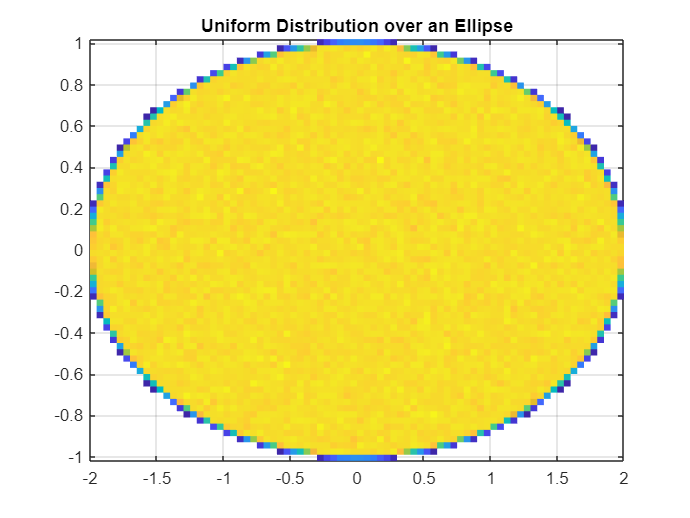

N = 10^7;
r = sqrt(rand(N,1));
theta = 2*pi*rand(N,1);

X= 2*r.*cos(theta);
Y = r.*sin(theta);

histogram2(X,Y,DisplayStyle="tile");
title("Uniform Distribution over an Ellipse");

(c) (8 points) Consider a triangle in a 2D Euclidean plane with vertices at (0, 0), (π, 0), (π/3, exp(1)). Propose an implementable algorithm for generating random points (in 2D) distributed uniformly inside the triangle. 

Consider the triangle with vertices (0,0),(0,1),(1,1). We know that a non singular linear transformation on a convex cone is again a convex cone(it is easy to see this; let us say that $\exists $ a vector $x = \lambda u + (1-\lambda)v
$ where $u, v$ are two vectors along two different edges in the initial convex cone. Now, let us say that the initial convex cone is subjected to a non-singular linear transformation $A$. Now, we observe that $x \rightarrow Ax, u \rightarrow Au, v \rightarrow Av$

 and using the initial convex cone condition, we have $Ax = \lambda Au + (1-\lambda) Av$ where $Au, Av$ are the vectors along the new edges. Now, given two points on two adjacent edges in this transformed system, we can apply a reverse linear transformation $A^{-1}$ to get points in the original space, and by the above derived property, (viewing $A^{-1}$ as the linear transform being applied on this set), we have retrieved $x = \lambda u + (1-\lambda)v
$  which means that every point in the transfomed set has a corresponding image in the original convex cone and every point in the original set also produes a valid point in the transformed set. Hence, a non-singular linear transform applied on a convex cone again gives us a convex cone.)

Using this, we now say that $\exists$ a matrix $A$ such that $A[1, 0]^T = [\pi, 0]^T, A[1, 1]^T = [\pi /3, e]^T$. This means that $A[1, 0; 1, 1]^T = [\pi, 0; \pi /3, e]^T$ . Computing A by calculating the inverse of that matrix, we get $A = [\pi, 0; -2\pi /3, e]^T$. 

Now we randomly select x, y from [0, 1]. Now since we have carried out our analysis for the traingle (0,0), (1,0), (1,1), we would also like our randomly generated variables x, y to lie inside that triangle. For that we follow the procedure:

function generate_x_y():

- temp_x = gen_rand()

- temp_y = gen_rand()

- x = max(temp_x, temp_y)

- y = min(temp_x, temp_y)

- return x, y

In this way, we are making sure that our random variables x, y satisfy the property of falling inside that traingle. Also, P(x, y) is a uniform distribution inside that traingle (0 outside the triangle). Now we prove that the distribution is uniform in the transformed random variable too.

Let $ X = [x, y]$ represent the multivariate random variable which uniformly samples points from the traingle (0, 0), (1, 0), (1, 1). We look at the random variable $Y = AX$. $P(Y) = \frac{P(X)}{|det(A)|}$ and $A$ is a constant matrix with $P(X)$ being the probability distribution of a uniform distribution over that traingle. Since both of them are constant, we find that $P(Y)$ is also constant and hence $Y$ also is a uniform random variable.

After generate_x_y(), we have a point in the triangle (0, 0), (1, 0), (1, 1). Now, we apply the matrix A to get a point in the desired traingle. 

function sample_from_desired_traingle():

- x, y = generate_x_y()

- z = A[x, y]

- return z

(d) (5 points) Implement the algorithm described in the previous sub-question. Use it to sample N = 107 independent points (in 2D) and plot a 2D histogram of the sample. You may use the Matlab function histogram2(), e.g., with ’DisplayStyle’ as ’tile’.

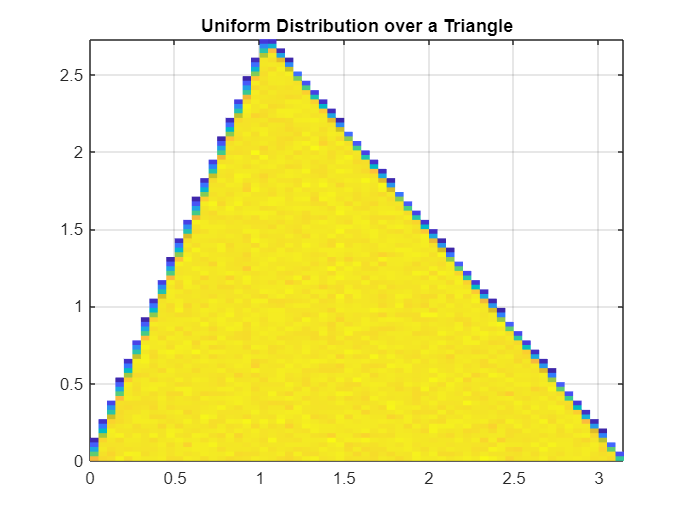

N=10^7;
Xs = rand(N,2);
Xmax = max(Xs,[],2);
Xmin = min(Xs,[],2);

x = pi*(Xmax - 2*Xmin/3);
y = exp(1)*(Xmin);

histogram2(x,y,DisplayStyle="tile")
title("Uniform Distribution over a Triangle");